Sam Kramer 

Dr. Alfred Wicks

ME 5714: Digital Signal Processing

## Midterm

%{
    This will be a script that will be used to complete the first take home
    midterm for ME 5714 -- Digital Signal Processing. It will require 4
    different parts to complete.

    Sam Kramer
    March 11th, 2023
%}

% --Script setup
    clear; clc; close all; format compact;

In class I related an experience related to converting 60Hz AC power to other desired frequencies by strategically switching current on and off. A similar technique is used in dimmer switches. The circuit below is the approached used. By the way, the circuit is totally background and does not play a role in this exam.

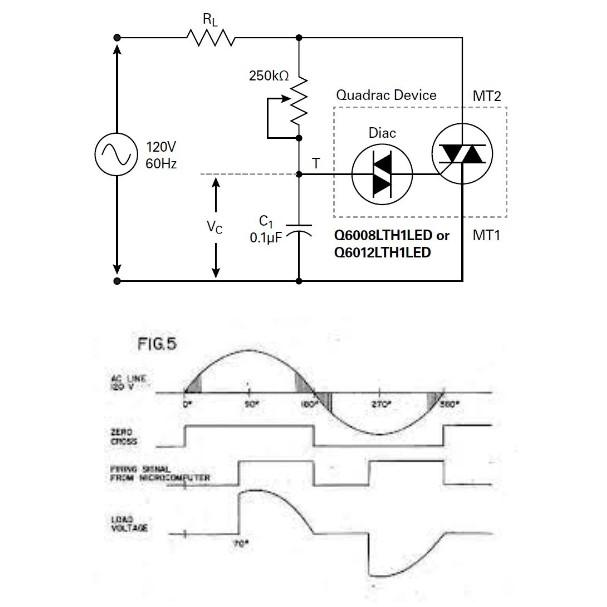

Using the voltage signal shown in the figure above, answer the following questions. Please show all work and submit answers using Matlab live script files. Be sure to label plots appropriately.

- For the voltage signal, model the signal using a Fourier series. Include at least the first 10 terms of the series keep in mind this is a voltage at 60 Hz with the rms amplitude of 120 volts. 

- Sample the signal at 20 samples per cycle and calculate the appropriate the discrete components. Plot the Re and Im components. Be sure they are scaled correctly.

- Sum the components of the DFT and the Fourier series to recreate the signal, overlay these plots to compare to the continuous signal. Briefly discuss the differences you observe.

- Given the data file, LS data, fit a second order equation to the data, Perform an FFT on the residuals. Is there deterministic content in residuals? What are they? 

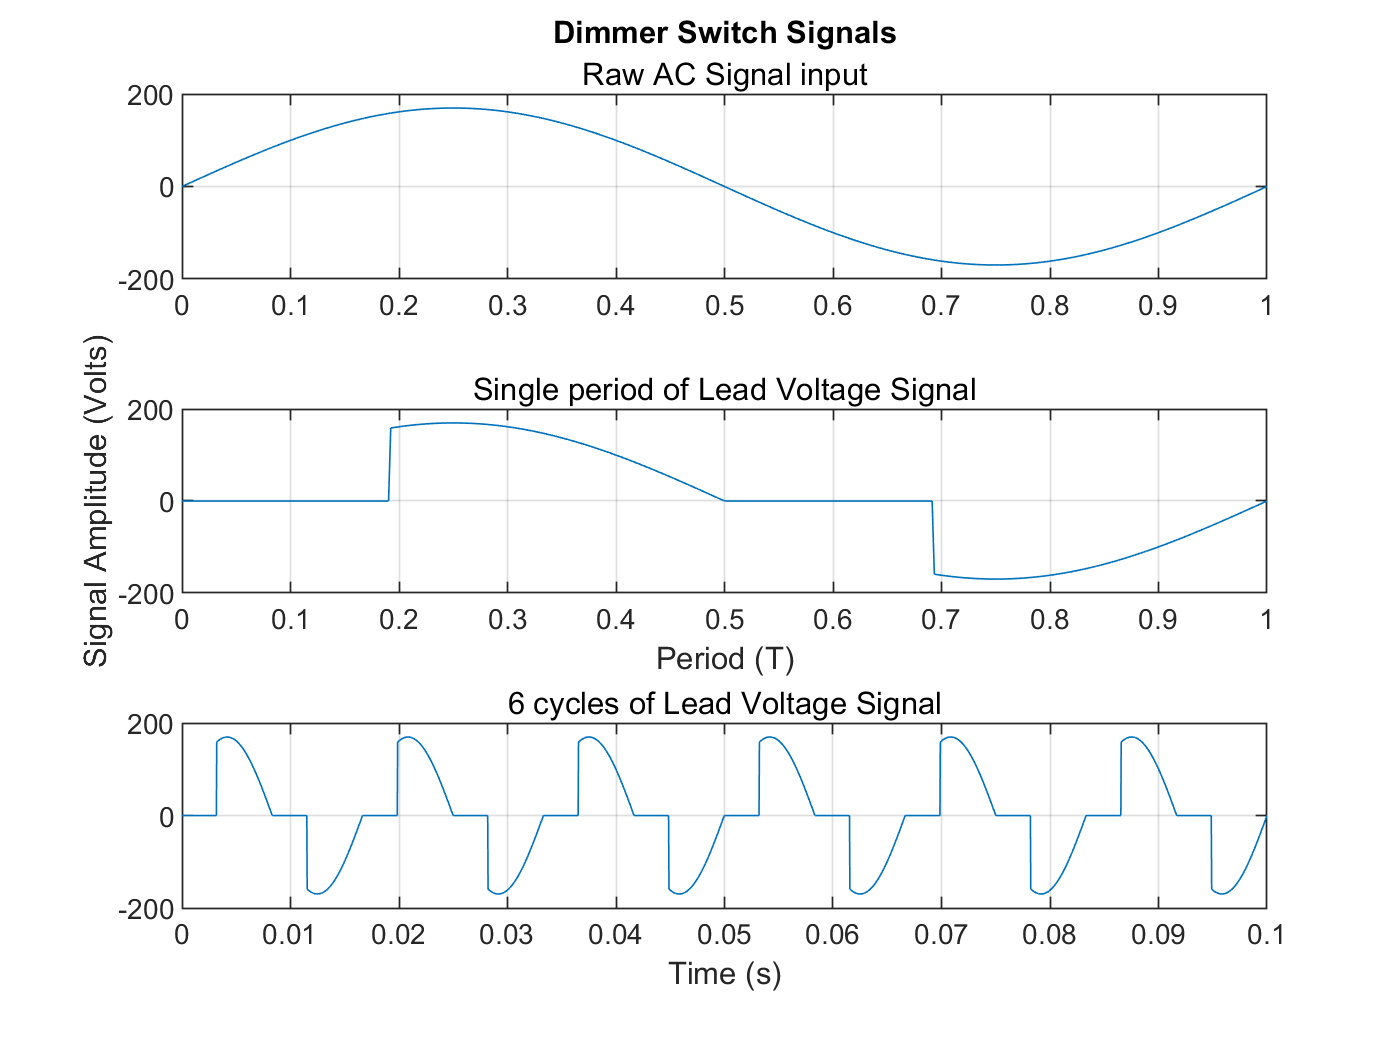

% --Wave parameters
    fs = 20;                        % Sample frequency (samples/cycle)
    ac_freq = 60;                   % AC signal frequency (Hz)
    w0 = 2 * pi * ac_freq;          % Signal frequency (rad/s)
    ac_amp_rms = 120;               % RMS AC Amplitude (Volts)
    ac_amp = sqrt(2) * ac_amp_rms;  % Signal Peak amplitude (V)
    leng = 500;                     % Length of vectors
    wave = zeros(1,leng);           % Wave solution vector
    sig_T = 1/ac_freq;              % Period of one cycle
    time = linspace(0,sig_T, leng); % Time vector for signal wave
    
% --Original Sine Wave generation
    sine_wave = ac_amp*sin(w0*time);
    T = leng;                       % Length of one cycle
    switch1 = round(7*T/36);        % Switch on at 70deg phase
    switch2 = round(25*T/36);       % Switch on a 250deg phase
    
% --Construction of Wave
    wave(switch1:T/2) = sine_wave(switch1 : T/2);
    wave(switch2:T) = sine_wave(switch2 : T);
    
% --Plot signal wave
    figure(1)
    subplot(3,1,1)
    period360 = time./max(time);
    plot(period360,sine_wave)
        hold on 
        grid on
        subtitle('Raw AC Signal input')
        title('Dimmer Switch Signals')
        
% --Plot Lead Voltage Signal
    subplot(3,1,2)
    plot(period360, wave)
        hold on
        grid on
        xlabel('Period (T)')
        ylabel('Signal Amplitude (Volts)')
        subtitle('Single period of Lead Voltage Signal')
        
    wave6 = [wave wave wave wave wave wave]; 
    time = linspace(0,6*sig_T, length(wave6));
        
    subplot(3,1,3)
    plot(time, wave6)

        grid on
        hold on
        xlabel('Time (s)')
        subtitle('6 cycles of Lead Voltage Signal')

## Part 1: Modeling the signal with a Fourier Series

    Handwritten work for part 1:

    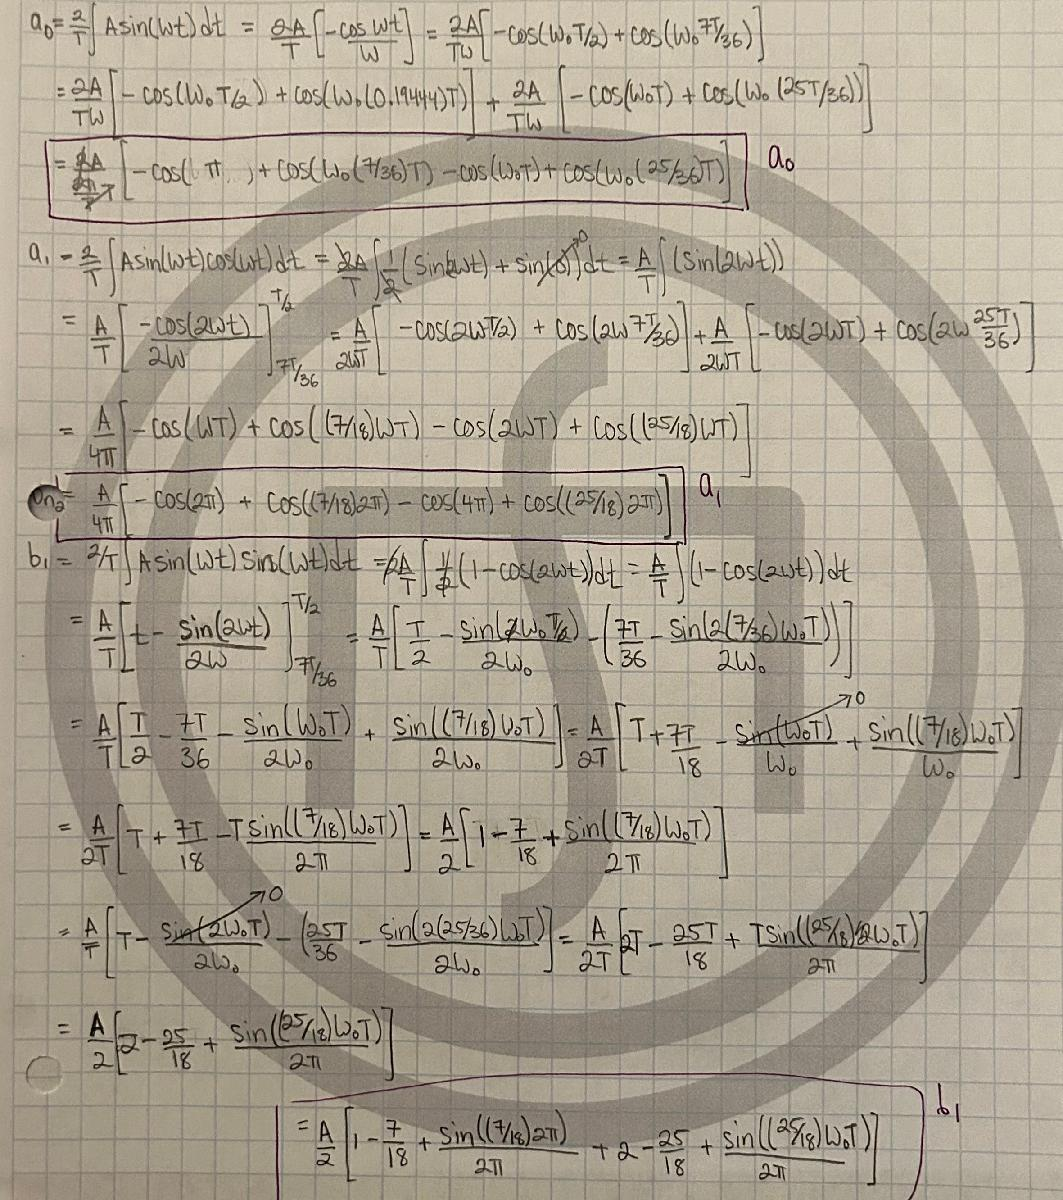

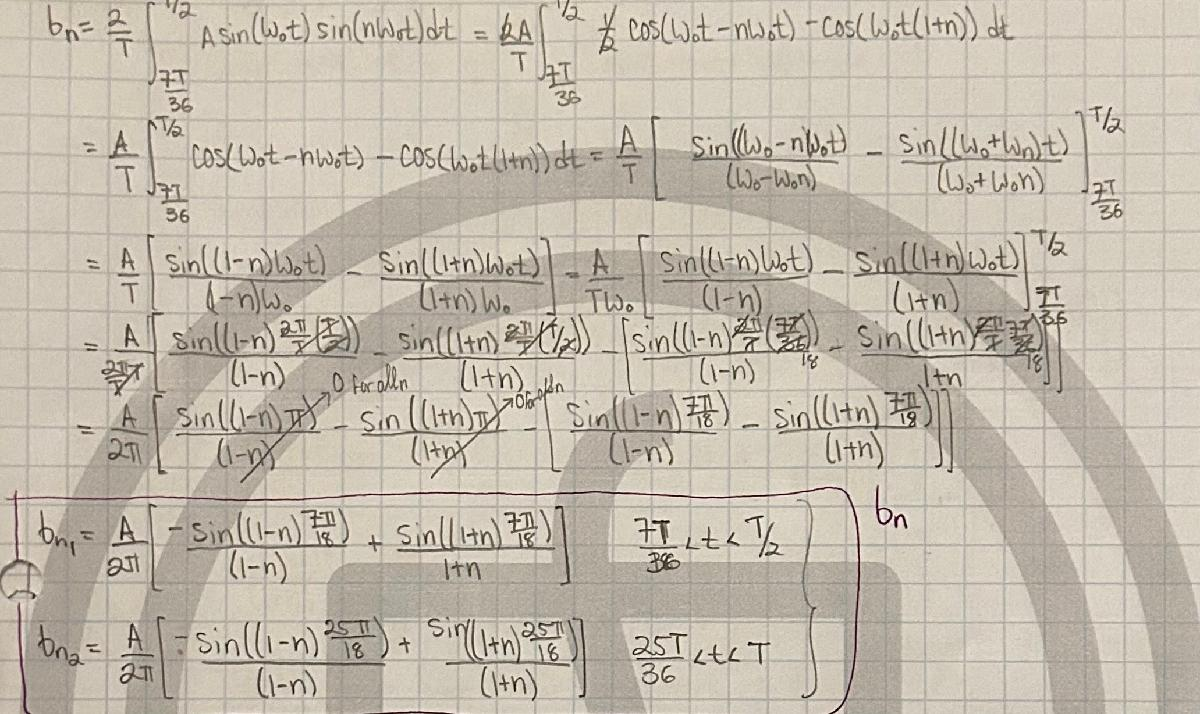

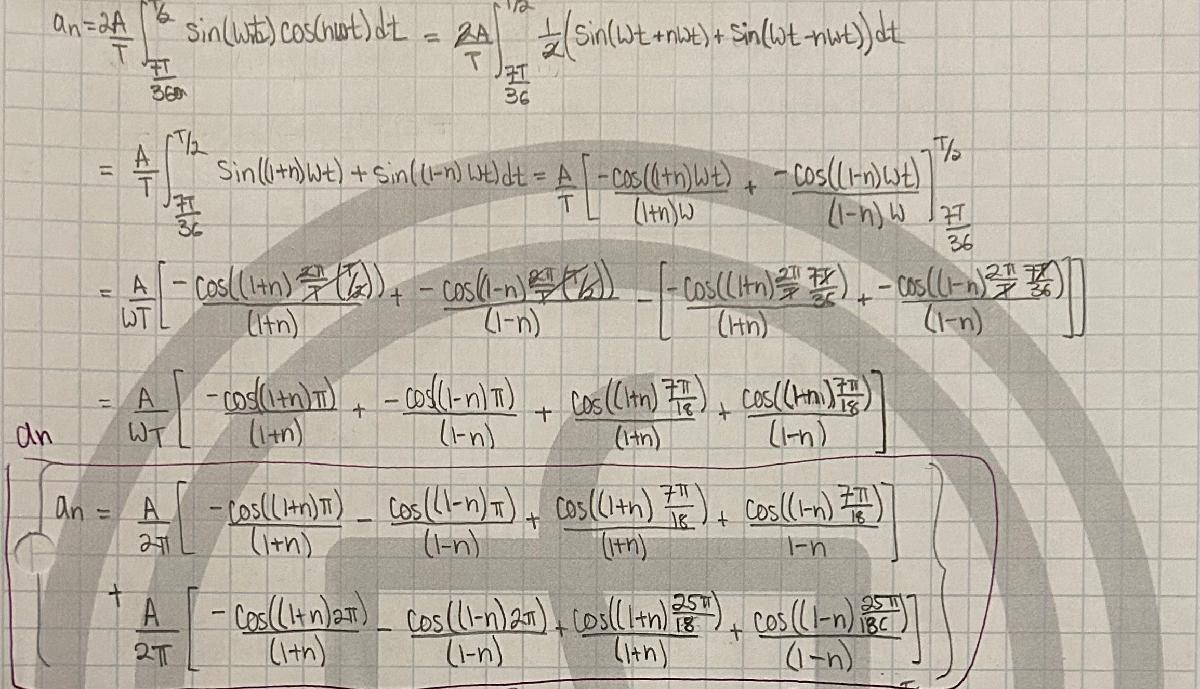

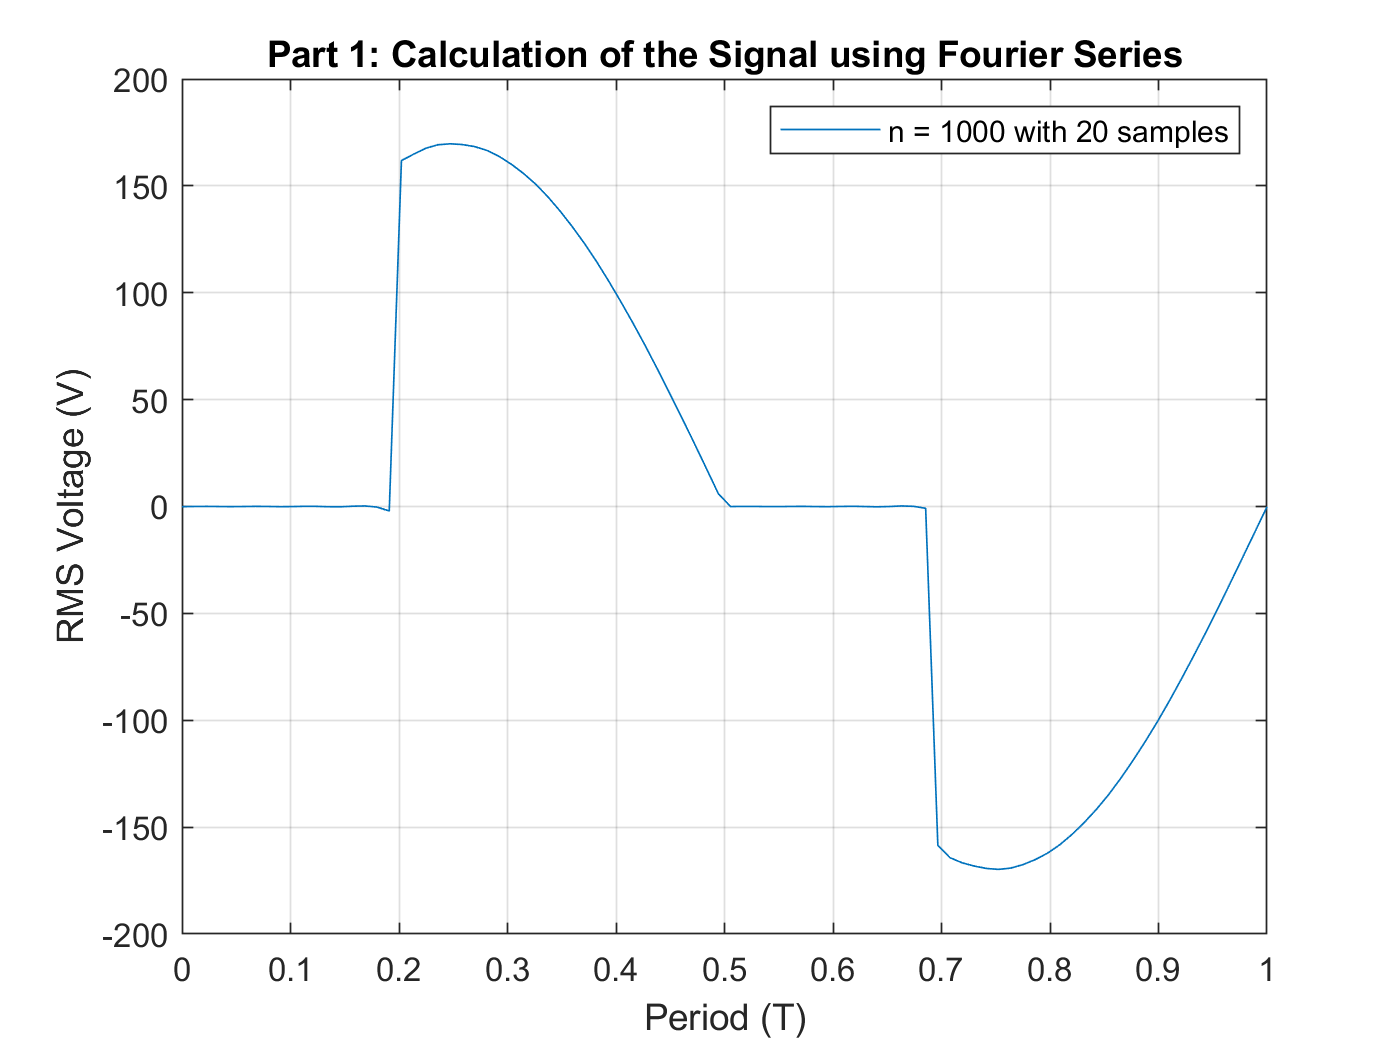

% --Setting up the Fourier Series Reconstruction
    A = ac_amp;                 % Amplitude of the signal
    a = [];                     % an solution vector
    b = [];                     % bn solution vector
    terms = 1000;               % Series of 100 sine terms
    waven = 0;
    
% --Reformat for 20 samples per cycle
    leng = 90;                          % Length of signals
    T = leng;                           % Length of one cycle
    switch1 = round(7*T/36);            % Switch on at 70deg phase
    switch2 = round(25*T/36);           % Switch on a 250deg phase
    time = linspace(0,sig_T, leng);     % Time vector for signal wave 
    period = time./max(time);           % Define period vector
    
% --Hardcode a0 for the series
    a0 = (A/pi)*(-cos(pi) + cos((7/36)*2*pi) - cos(2*pi) + cos((25/36)*2*pi));
    waven = waven + a0;         % Add in a0 to wave function
    
% --Hardcode a1 for the series
    a1 = (A/(4*pi)) * (-1 + cos((7/18)*2*pi) - 1 + cos((25/18)*2*pi));
    a = [a a1];                     % store values for a1 in an vector
    
% --Hardcode b1 for the series
    b1 = (A/2)*(1 + 2 - (7/18) - (25/18) + (sin((7/18)*2*pi))/(2*pi) + (sin((25/18)*2*pi))/(2*pi));
    b = [b b1];                 % Store b values
    
% --Loop to calcualte an and bn values
    for n = 2:terms
        
        % --Calculate an
            T1 = (-cos((1+n)*pi)/(1+n)) - (cos((1-n)*pi)/(1-n)) + (cos((1+n)*((7/36)*2*pi))/(1+n)) + (cos((1-n)*((7/36)*2*pi))/(1-n));
            T2 = (-cos((1+n)*2*pi)/(1+n)) - (cos((1-n)*2*pi)/(1-n)) + (cos((1+n)*(25/36)*2*pi)/(1+n)) + (cos((1-n)*(25/36)*2*pi)/(1-n));
            an_1 = T1*A/(2*pi);
            an_2 = T2*A/(2*pi);
            an = an_1 + an_2;
        
        % --Store an values
            a = [a an];        % Final an vector
            
        % --Calculate bn values
            bn_1 = (A/(2*pi)) * (-sin((1-n)*(7*pi/18))/(1-n) - sin((1-n)*(25*pi/18))/(1-n));
            bn_2 = (A/(2*pi)) * (sin((1+n)*(7*pi/18))/(1+n) + sin((1+n)*(25*pi/18))/(1+n));
            bn = bn_1 + bn_2;
            
        % --Store bn values
            b = [b bn];        % Final bn vector
    end
    
% --Calculate series values
    %b = zeros(1,terms);
    for n = 1:terms
        
        % --Calculate the different series waves for entire period
            waven = waven + a(n)*cos(n*w0*time) + b(n)*sin(n*w0*time);
        
    end
% --Reformat solution
    xt = waven;
    
% --Plot
    figure(2)
    plot(period,xt)
        hold on 
        grid on
        xlabel('Period (T)')
        ylabel('RMS Voltage (V)')
        title('Part 1: Calculation of the Signal using Fourier Series')
        legend('n = 1000 with 20 samples')

## Part 2: DFT of the Signal

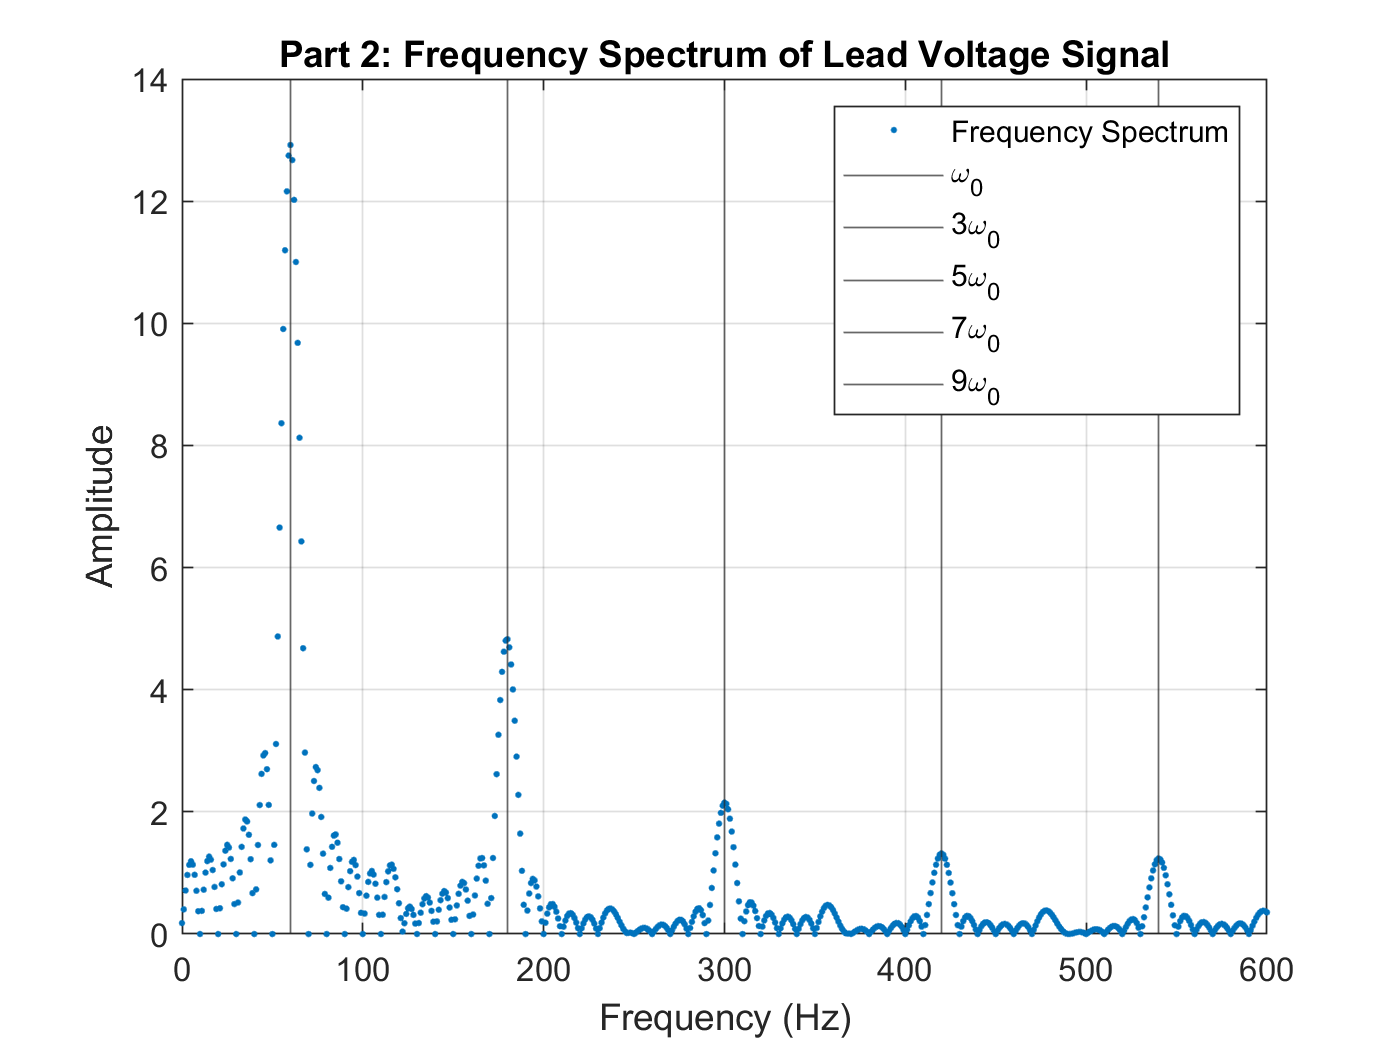

% --Zero pad data
    reps = 6;
    z = zeros(1,leng*ac_freq - reps*leng);          % Zero pad of system
    xt6 = [xt xt xt xt xt xt z];                    % Continue 6 cycles of signal
    xt6 = xt6(1:leng*ac_freq);
    T = sig_T*ac_freq;
        
% --Setup of DFT of Signal
    N = length(xt6);                        % Samples of the signal
    sol_amplitude = [];                     % Solution amplitude vector
    n = 0:N - 1;                            % Temporal Index of system
    Cn = [];                                        % Cn vectors
    
% --Perform DFT of Signal
    for m = 0:(1/T):(N - 1/T)               % Frequency index
        
        % --First exponent term
            C = (exp((-1i*2*pi*m*n)/N))';
            
        % --Complete Cm calculation and calculate amplitude
            magnitude = sum(xt6 * C);
            Cn = [Cn magnitude];
            amplitude = 2*abs(magnitude)/N;
        
        % --Save values
            sol_amplitude = [sol_amplitude, amplitude];
        
    end

% --Format frequency vectors
    freq = 0:(1/T):(N - 1/T);
    
% --Plot DFT of Signal
    figure(3)
    plot(freq, sol_amplitude,'.')
        hold on
        grid on
        xlim([0 600])
        ylabel('Amplitude')
        xlabel('Frequency (Hz)')
        xline(60)
        xline(180)
        xline(300)
        xline(420)
        xline(540)
        legend('Frequency Spectrum','\omega_0' ,'3\omega_0','5\omega_0','7\omega_0','9\omega_0')
        title('Part 2: Frequency Spectrum of Lead Voltage Signal')

## Part 3: Summing DFT and Fourier Series and Overlaying on Original signal

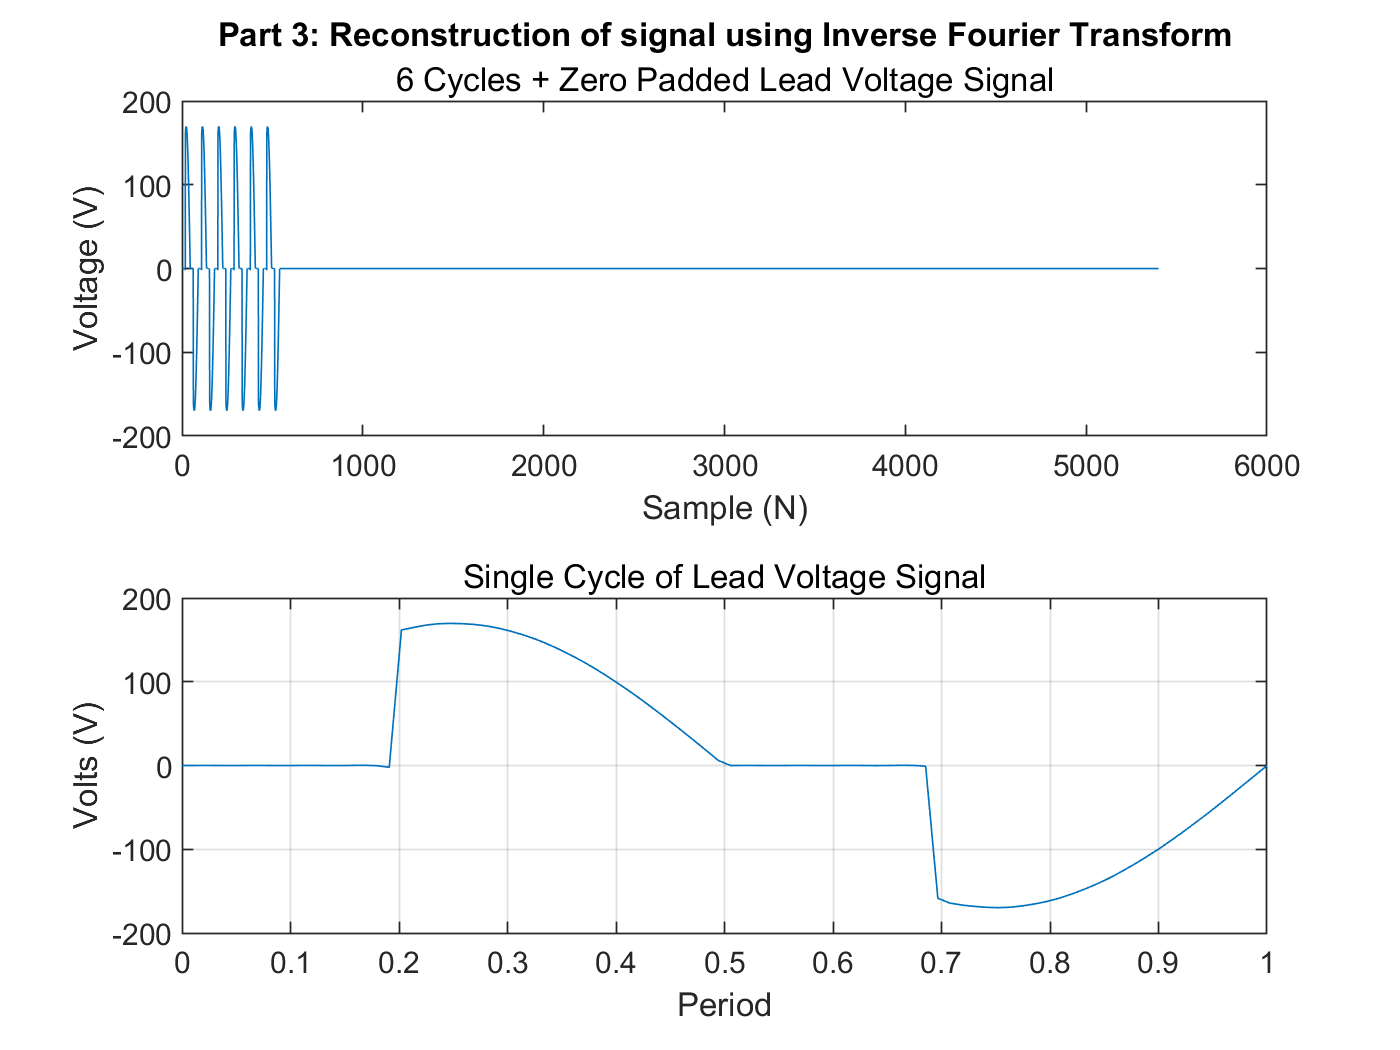

% --Setup System
    N = length(sol_amplitude);      % Length of the solution vector
    ht = [];
    
% --For loop
    for k = 0:N-1
        
        % --Calculation of first term (Transposed)
            W = (exp((1i*2*pi*k*n)/N))';
            
        % --Summation term using dot product 
            XN = sum(Cn * W);
            
        % --Normalizing and getting into cartesian coords
            YT = sign(real(XN))*abs(XN)/N;
            
        % --Store values to plot
            ht = [ht YT];  
        
    end

% --Reformat ht values
    ht2 = ht(1:length(period));

% --Plot output of signal
    figure(4)
    subplot(2,1,1)
    plot(ht)
        xlabel('Sample (N)')
        ylabel('Voltage (V)')
        subtitle('6 Cycles + Zero Padded Lead Voltage Signal')
        title('Part 3: Reconstruction of signal using Inverse Fourier Transform')
        
    subplot(2,1,2)
    plot(period, ht2)
        subtitle('Single Cycle of Lead Voltage Signal')
        hold on
        grid on
        xlabel('Period')
        ylabel('Volts (V)')

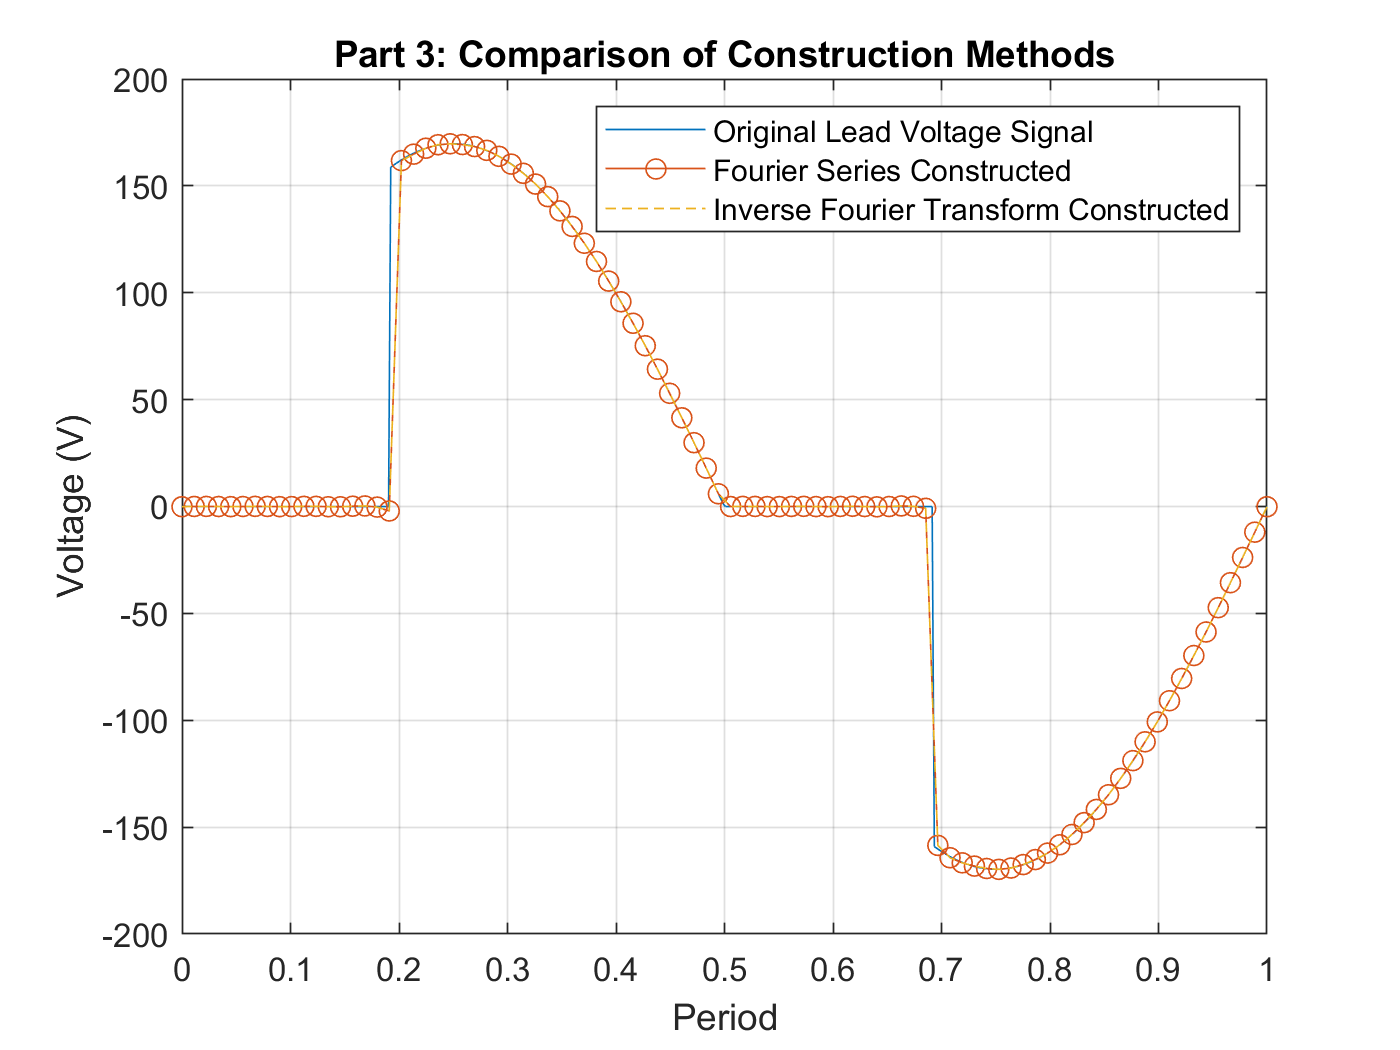

        
% --Plotting all 3 Signals on top of each other
    figure(5)
    plot(period360,wave)
        hold on
    plot(period,xt, '-o')
    plot(period,ht2,'--')
    legend('Original Lead Voltage Signal','Fourier Series Constructed','Inverse Fourier Transform Constructed')
        grid on
        xlabel('Period')
        ylabel('Voltage (V)')
        title('Part 3: Comparison of Construction Methods')

    After overlaying all three of the signals on top of eachother, they look fairly alike. The large difference is between the original, which was assumed to be continuous, versus the discrete signals constructed using the Fourier Series and the Inverse Fourier Transfrom. The only noticeable difference is when matlab plays "dot-to-dot." This can cause the function to appear different because they are discretized. The maximum of the amplitude also does not reach the same value because of this phenomenon. The tips are slightly clipped off causing the RMS values to be slightly off too, however not by much.

## Part 4: LS Data Fit

% --Load in data
    data = load('midterm_data.mat');
    xt = data.xt;
    time = 0:length(xt) - 1;
    
% --Plot Data
    figure
    subplot(2,1,1)
    plot(time,xt)
        hold on
        grid on 
        xlabel('Time (s)')
        ylabel('Amplitude')
        title('Part 4: Fitting Polynomial to LS Data')
        
% --Develop Fit to system
    ft = fittype( 'poly2' );
    [fitresult, gof] = fit(time', xt', ft );
    
% --Extract residuals
    fitsystem = fitresult(time);
    resids = xt' - fitsystem;
    
% --Plot fit to signal and residuals
    plot(time, fitsystem);
        subtitle('Fit to Signal')
        hold on
        grid on
        xlabel('Time (s)')
        legend('LS Data', 'Fitted Polynomial')
        
    subplot(2,1,2)
    plot(time,resids,'.')
        grid on
        hold on
        subtitle('Residuals of Fit')
        
% --Perform DFT on residuals plot
    fft_resid = fft(resids);
    magnitude = abs(fft_resid);
    amplitude = (2*magnitude)/length(resids);
    
% --Format Frequency
    freq = 0:1:length(resids) - 1;
    figure
    stem(freq,amplitude)
        hold on
        grid on
        xlabel('Frequency (Hz)')
        ylabel('Amplitude')
        xline(50,'linewidth',1.5,'Color',[0.6 0.3 0.3])
        legend('DFT of Residuals','Nyquist Frequency')
        title('Fourier Transform of Fit Residuals')

    When we look at the fourier transform of the residuals data, we can see that there is clearly a peak at a specific frequency, whereas all the others have zero or close to zero. This means that there is one dominant frequency and there is little noise because there are no other spikes in the frequency spectrum up to the nyquist frequency. The deterministic content will be a periodic wave.